# Temporal Modulation Filtering and Wavelet Analysis of Recorded Speech

### 2.1 Title and Author Information

ELEC5305 Acoustics, Speech and Signal Processing | Audio Processing Report 2

Author: Yixiang Ma | Student ID: 550762913 | Date: 29 October 2026

Tested environment: MATLAB R2026a Update 5 with Signal Processing Toolbox (resample and hann) and Wavelet Toolbox (cwt). Input audio and all custom helpers are included in the submission folder.

clear; close all; clc;
reportFolder = pwd;
if ~isfile(fullfile(reportFolder,'voicebank_p232_003.wav'))
    reportFolder = fullfile(pwd,'Report2 YixiangMa');
end
assert(isfile(fullfile(reportFolder,'voicebank_p232_003.wav')), ...
    'Set Current Folder to the extracted Report2 YixiangMa folder.');
addpath(reportFolder);
assert(exist('resample','file')==2 && exist('hann','file')==2, ...
    'Signal Processing Toolbox is required (resample and hann).');
assert(exist('cwt','file')==2, 'Wavelet Toolbox is required.');

### 2.2 Objective

This report examines how restricting temporal modulation changes recorded speech. It compares 4, 8, and 16 Hz temporal low-pass (LP) masks applied through a two-dimensional Fourier transform of the log-magnitude spectrogram. Reconstruction is checked before comparing waveform and envelope fidelity. Continuous wavelet analysis adds a local time-frequency view. Unlike Report 1's synthetic-signal finite impulse response (FIR) noise reduction, this experiment concerns speech dynamics. It does not test denoising or improved intelligibility.

### 2.3 Background

The short-time Fourier transform (STFT) tracks acoustic frequency content over time. Window length sets the time-frequency trade-off, and the hop sets the spectrogram's temporal sampling rate. A second Fourier transform across the spectrogram reveals temporal modulation in hertz and spectral modulation in cycles per kilohertz [1,3,4]. These axes describe changes in spectral patterns, not the waveform's acoustic frequencies.

Speech-modulation studies motivate the choice of low temporal rates, but acoustic similarity alone does not establish intelligibility [3]. The present experiment filters log magnitude and retains the original STFT phase. That combination need not be a consistent STFT of any waveform. Comparing the target with the reconstructed waveform's STFT measures this mismatch.

The continuous wavelet transform (CWT) offers a scale-dependent comparison with the STFT. High-frequency wavelets are shorter in time than low-frequency wavelets. The analysis uses MATLAB's analytic Morlet wavelet with L1 normalisation [2,5]. Coefficients affected by the signal boundaries, as identified by the cone of influence (COI), are excluded from the displayed scalograms [6].

### 2.4 Methodology and Implementation

VoiceBank utterance p232_003.wav from Edinburgh [7] is an unchanged clean public recording, not a personal recording. MATLAB resample converts 48 kHz to 16 kHz with anti-alias filtering [8]. After mean removal and peak scaling to 0.8, every condition uses a 512-sample periodic Hann window (32 ms), a 128-sample hop (8 ms; 125 Hz frame rate), and a 512-point fast Fourier transform (FFT).

Log magnitudes are floored 120 dB below their maximum. Reflection adds 63 neighbouring frames (about 0.5 s) per boundary. Even temporal masks pass rates up to 0.8 times their stop frequency, taper with a raised cosine, and reach zero at 4, 8, or 16 Hz. Spectral modulation is unchanged. The masks preserve real log magnitudes; original-phase synthesis uses squared-window overlap normalisation. Bypass reconstruction uses the original complex STFT without the log floor. Outputs have equal length.

A 4/16 Hz log-spectrogram calibration checks the masks. Fidelity excludes the first and last 0.5 s. Measures include reference-to-error signal-to-noise ratio (SNR), 20 ms root-mean-square (RMS) envelope correlation, log-spectrum root-mean-square error (RMSE), and STFT consistency. No output gain fitting or delay search is used. Listening WAV files alone share one attenuation. CWT uses an 800 ms event centred on the largest reference RMS-envelope change outside 0.7 s margins. This one-utterance experiment is offline, not a listening study or causal system.

The equations use sample index n, acoustic-frequency bin k, frame m, window length L, hop H, FFT length N, and Hann window w.


$$S[k,m]=\sum_{n=0}^{L-1}x[n+mH]w[n]e^{-j2\pi kn/N}$$


A denotes floored log magnitude; M its two-dimensional transform, with F frequency rows and T time columns. Modulation axes follow the spectrogram sampling intervals, not the audio FFT axis.


$$A[k,m]=20\log_{10}(\max(|S[k,m]|,\epsilon)),\qquad M=\mathrm{FFT2}(A_{\mathrm{pad}})$$



$$f_t(v)=v\frac{f_s}{HT},\qquad \nu_s(u)=u\frac{1000}{F\Delta f},\qquad \Delta f=\frac{f_s}{N}$$


After applying the even mask B, the inverse two-dimensional FFT (IFFT2) is followed by cropping and phase restoration. Only display maps use row-mean removal and separable Hann tapering, not filtering or inversion.


$$\widetilde{A}=\mathrm{Re}\{\mathrm{IFFT2}(B\odot M)\},\qquad \widetilde{S}=10^{\widetilde{A}/20}e^{j\arg S}$$



$$\widehat{x}[n]=\frac{\sum_m w[n-mH]\widetilde{s}_m[n-mH]}{\sum_m w^2[n-mH]}$$


Padding keeps overlap weights positive over retained samples. The L1-normalised CWT uses scale a, shift b, and the conjugate Morlet wavelet. SNR measures waveform distortion against clean speech, not noise removal.


$$W_x(a,b)=\frac{1}{a}\int x(t)\psi^*\!\left(\frac{t-b}{a}\right)dt$$



$$\mathrm{SNR}=10\log_{10}\frac{\sum_n x[n]^2}{\sum_n(x[n]-\widehat{x}[n])^2}$$


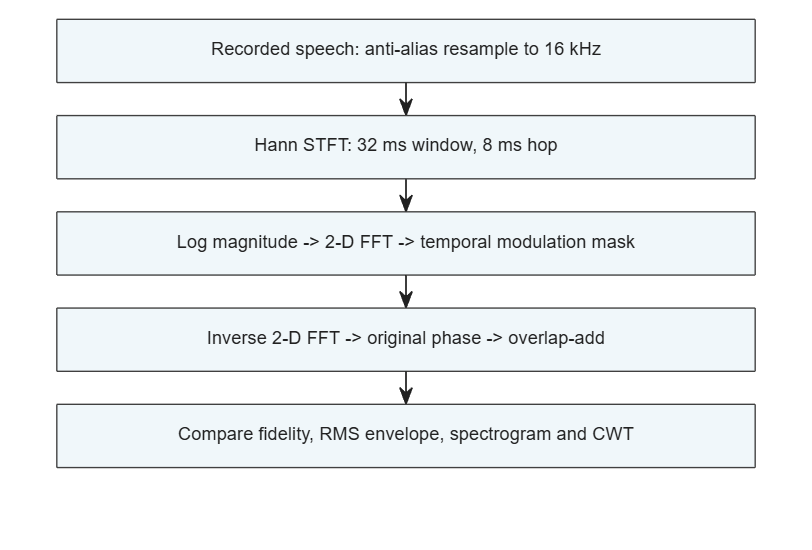

r2_plot([],1);

Figure 1. Processing pipeline. The CWT is an analysis branch after reconstruction, not a synthesis stage. All non-toolbox operations are included as separate r2_*.m helper files.

### 2.5 Code and Results

#### 2.5.1 Input preparation and reproducible analysis

[source, sourceFs] = audioread( ...
    fullfile(reportFolder,'voicebank_p232_003.wav'));
assert(sourceFs==48000 && size(source,2)==1);
fs = 16000;
x = resample(source,1,3);
x = x-mean(x);
x = 0.8*x/max(abs(x));
R = r2_analyse(x,fs);
fprintf('Duration: %.6f s; sample rate: %d Hz\n',numel(x)/fs,fs);

Duration: 7.184875 s; sample rate: 16000 Hz


fprintf('Score interval: %.3f to %.3f s\n',R.scoreRangeSeconds);

Score interval: 0.500 to 6.685 s


r2_stft and r2_istft implement padded analysis and synthesis. r2_modfilter applies reflection and the temporal mask. r2_analyse computes every condition and its metrics with shared settings. Execution uses only the submitted files and MATLAB toolboxes.

#### 2.5.2 Reconstruction and modulation calibration

for k=1:height(R.checks)
    fprintf('%s: %.3g (pass=%d)\n', ...
        R.checks.Check(k),R.checks.Value(k),R.checks.Passed(k));
end

Unit-gain STFT reconstruction: 2e-16 (pass=1)
Unmodified 2-D FFT round trip: 6.75e-16 (pass=1)
Constant log-spectrogram preservation: 1.78e-15 (pass=1)
4 Hz calibration amplitude error: 4.44e-15 (pass=1)
16 Hz calibration residual amplitude: 8.52e-15 (pass=1)
Maximum inverse-FFT imaginary error: 0 (pass=1)


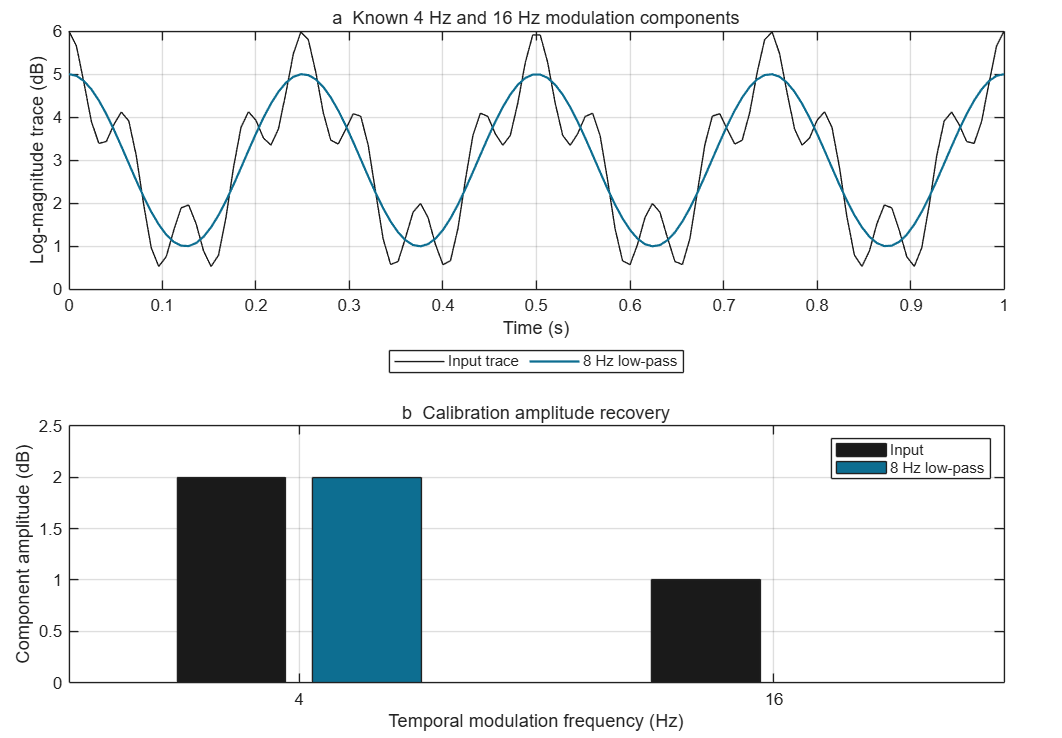

assert(all(R.checks.Passed));
r2_plot(R,2);

Figure 2. Algorithm-level calibration, not a speech intelligibility test. The input log-spectrogram trace contains 4 Hz and 16 Hz components with amplitudes 2 dB and 1 dB. An 8 Hz mask preserves the 4 Hz component and suppresses 16 Hz to numerical precision. Unit-gain speech reconstruction has relative error approximately 2e-16. The unmodified two-dimensional transform, constant-input, and real-valued inverse checks also pass.

#### 2.5.3 Modulation representation and parameter choices

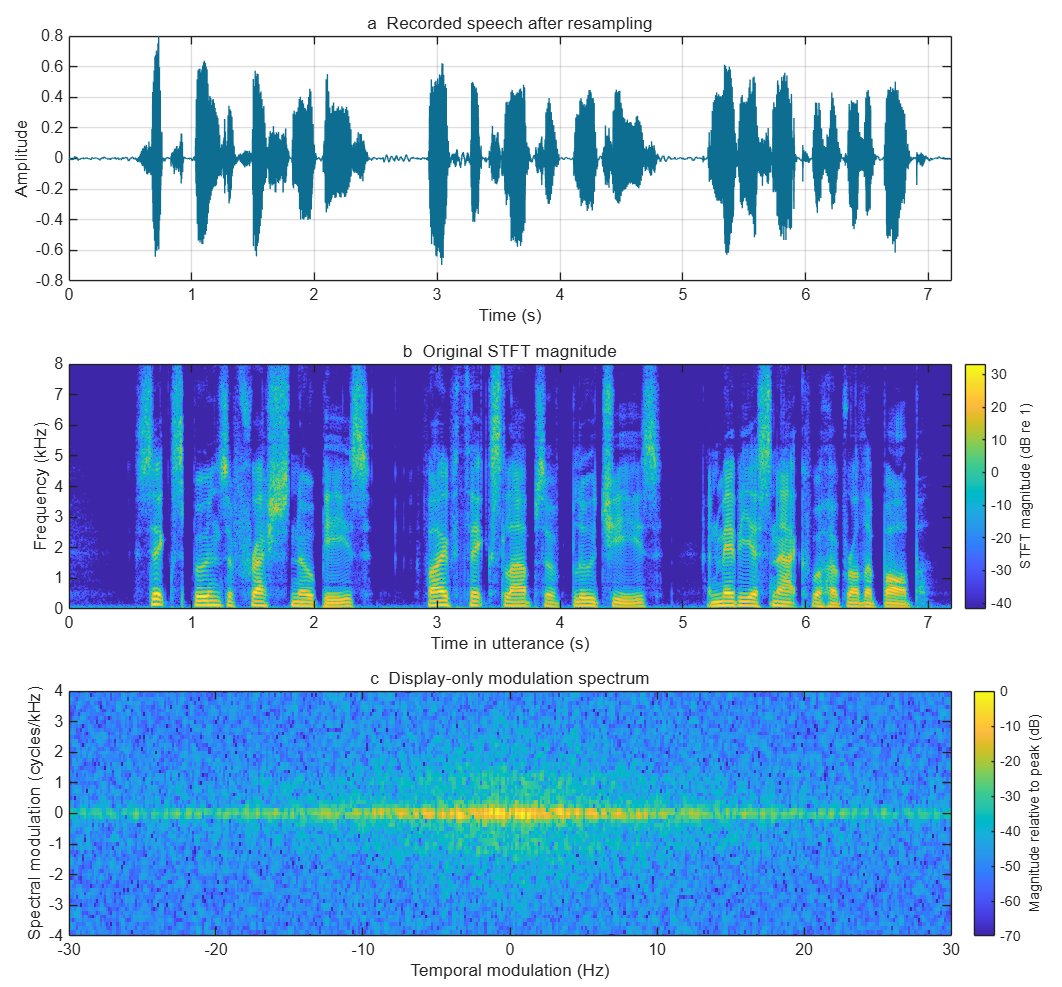

r2_plot(R,3);

Figure 3. Reference waveform, STFT magnitude, and display-only modulation spectrum. The modulation map uses a row-mean-removed, two-dimensional Hann-tapered log spectrogram and is normalised to its own peak. Its horizontal axis is temporal modulation in Hz; its vertical axis is spectral modulation in cycles/kHz.

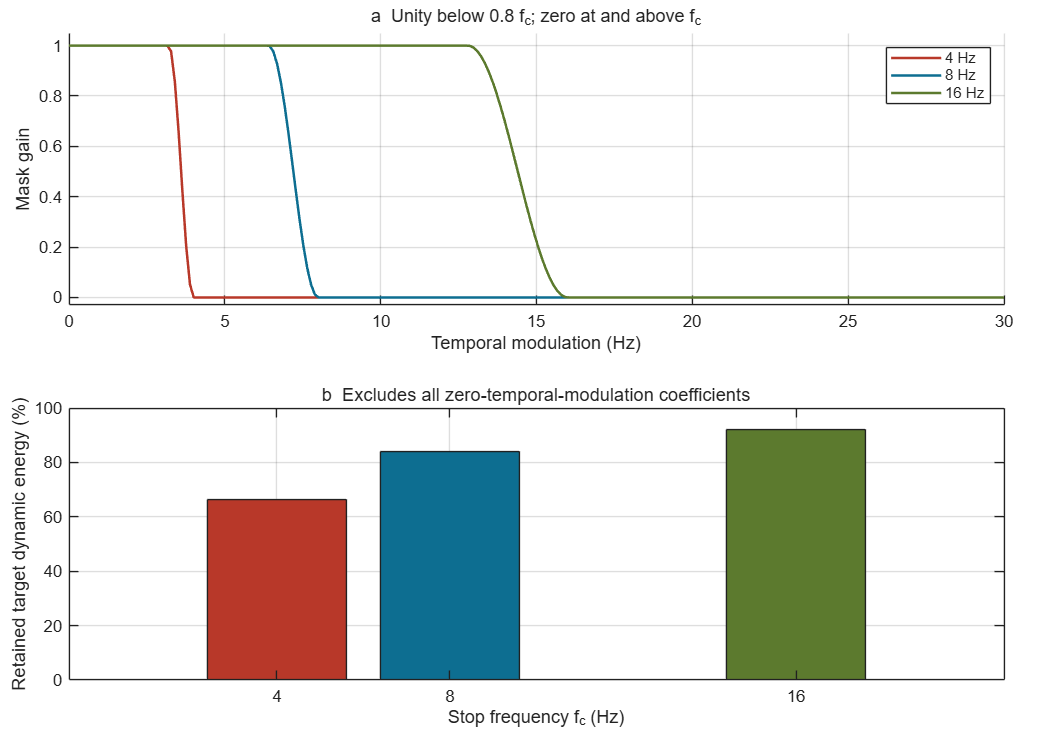

r2_plot(R,4);

Figure 4. Temporal mask responses and retained target dynamic-modulation energy. All coefficients with zero temporal modulation are excluded from this energy ratio, preventing static spectral structure from dominating the measure. The 4, 8, and 16 Hz masks retain 66.42%, 84.04%, and 92.28%, respectively. This is a target-spectrogram quantity, not a direct measurement of the reconstructed waveform's modulation energy.

The block below shows the 8 Hz calculation; the helper repeats it for each setting. Reflection reduces the artificial boundary join, but edge effects remain. The global FFT filter is still noncausal.

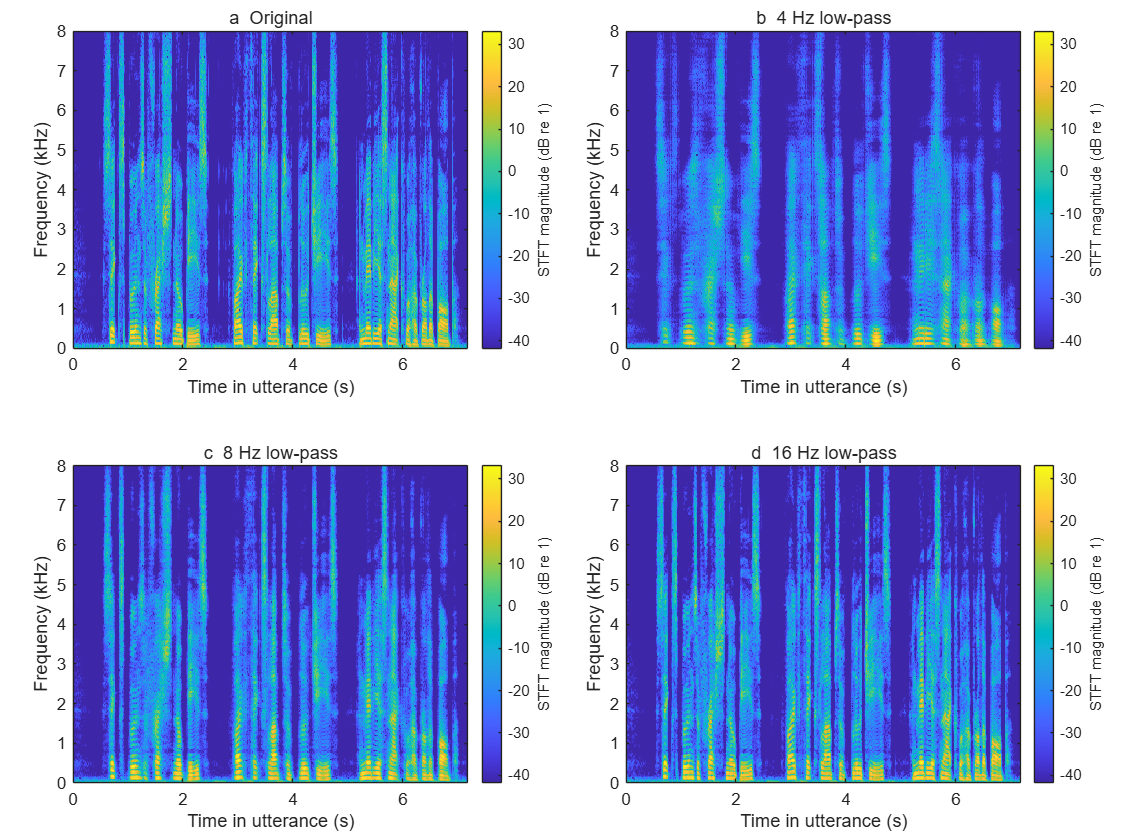

A = R.logMagnitude;
p = R.details{3}.paddingFrames;
A_pad = [A(:,p+1:-1:2), A, A(:,end-1:-1:end-p)];
M = fft2(A_pad);
B = ifftshift(R.details{3}.mask);
A_hat = real(ifft2(M.*B));
A_hat = A_hat(:,p+(1:size(A,2)));
S_hat = 10.^(A_hat/20).*exp(1i*angle(R.S));
S_hat([1 end],:) = real(S_hat([1 end],:));
x8 = r2_istft(S_hat,R.meta);
assert(max(abs(x8-R.outputs(:,3)))<1e-10);
r2_plot(R,5);

Figure 5. Reanalysed spectrograms of the original and three reconstructed waveforms. All panels use the same STFT grid and colour limits. These are actual reconstructed-output spectra, not the ideal filtered target matrices. Restricting modulation smooths temporal structure rather than imposing an acoustic low-pass cutoff at 4, 8, or 16 Hz.

#### 2.5.4 Quantitative fidelity and consistency

r2_print_metrics(R.metrics);

StopHz  Retained%  SNR_dB  EnvCorr  LogRMSE  Consistency
   Inf    100.00  313.98   1.0000     0.00    2.813e-16
     4     66.42    2.99   0.6206    10.99       0.2527
     8     84.04    5.70   0.8515     7.02       0.2088
    16     92.28   12.75   0.9763     4.21         0.16


Table 1. StopHz is the mask stop frequency (Inf denotes bypass); Retained% is target dynamic energy; EnvCorr is RMS-envelope correlation; LogRMSE is log-spectrum RMSE in dB; Consistency is relative complex-STFT error after reanalysis. Unlike the central-interval fidelity measures, consistency uses the complete padded STFT matrix. Bypass SNR is about 314 dB because only floating-point error remains, not a physical enhancement gain.

Increasing the cutoff from 4 to 16 Hz increased waveform SNR from 2.99 to 12.75 dB and reduced log-spectrum RMSE from 10.99 to 4.21 dB. The complete unrounded values are saved to generated/metrics.csv.

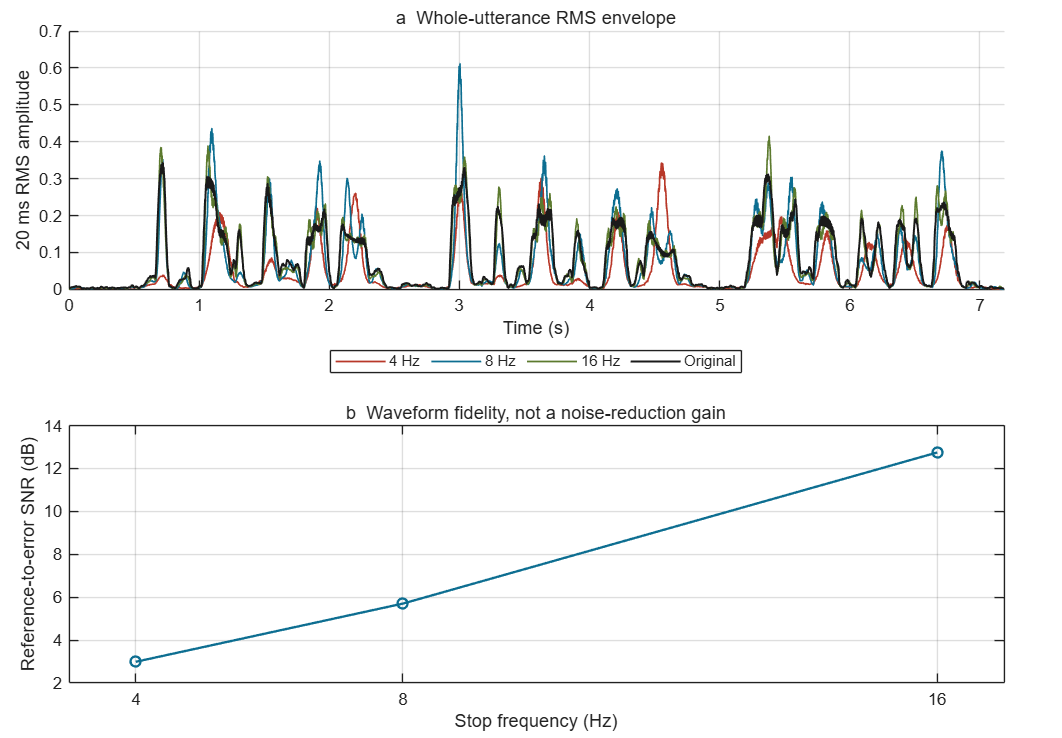

r2_plot(R,6);

Figure 6. Whole-utterance 20 ms RMS envelopes and scored waveform fidelity. The plotted envelopes include the boundaries for inspection, but all reported fidelity metrics exclude the first and last 0.5 s. The larger cutoff is closer to the original in this experiment; this does not establish better intelligibility.

#### 2.5.5 Local STFT and wavelet inspection

fprintf('Reference-selected event centre: %.4f s\n', ...
    (R.wavelet.eventSample-1)/fs);

Reference-selected event centre: 1.4931 s


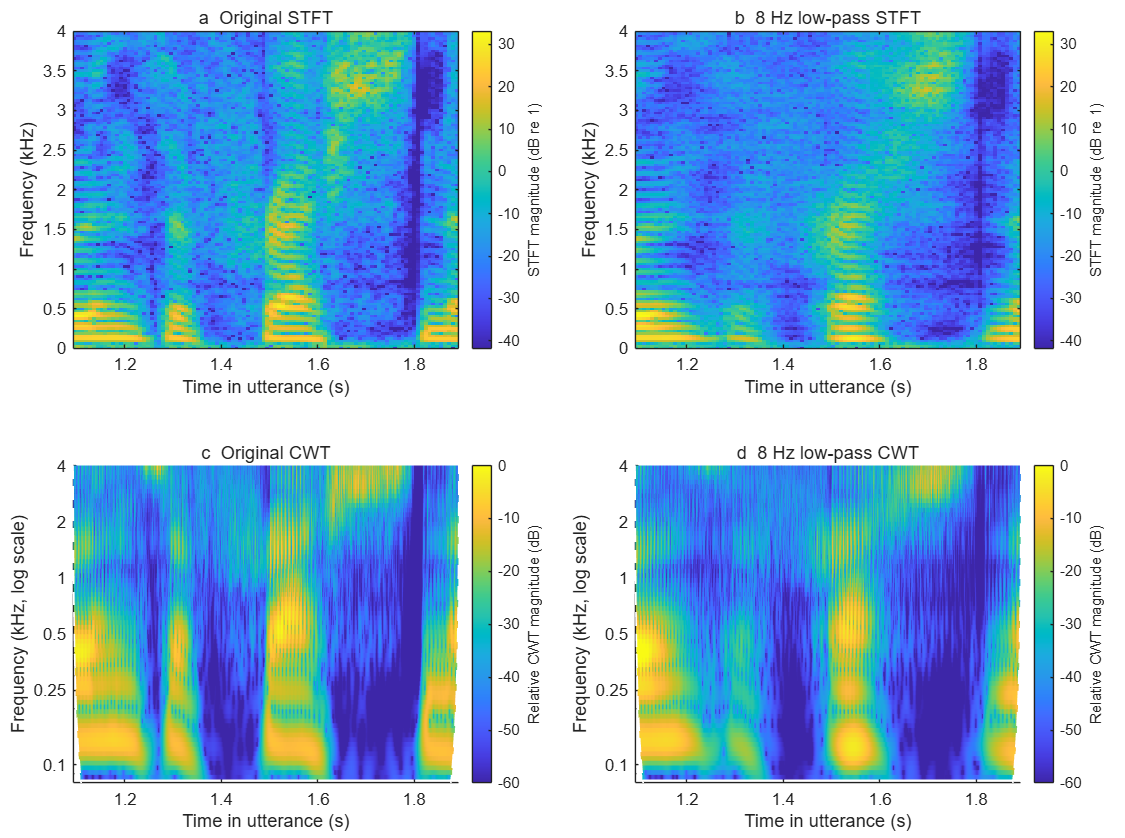

r2_plot(R,7);

r2_save(R,reportFolder);

Figure 7. One reference-selected 0.8 s event, comparing the original with the 8 Hz output. The upper row uses the same linear-frequency STFT scale. The lower row uses analytic Morlet CWT magnitudes on a logarithmic frequency axis, normalised to the original CWT peak with shared limits. COI-sensitive coefficients are omitted; dashed lines mark the COI where visible. STFT and CWT colours are not numerically interchangeable. The event is selected from the original envelope only, not from favourable output scores.

Optional listening: original.wav and modulation_lp4/8/16.wav are saved under generated/. They share one attenuation; none is independently peak-normalised. Listening is optional and is not part of the automated validation.

### 2.6 Discussion

Lower temporal cutoffs removed faster changes and reduced similarity to the original speech (Table 1). The 16 Hz condition retained more target dynamic-modulation energy and had higher envelope correlation than the 4 Hz condition. This follows the nested masks: a larger cutoff preserves additional coefficients. It does not make 16 Hz an optimal setting. The experiment measured fidelity without testing a competing noise-removal benefit.

A 4 Hz temporal mask smooths changes across acoustic-frequency channels; it does not limit the audio waveform to frequencies below 4 Hz. The spectrograms in Figure 5 help distinguish these effects. CWT offers a different temporal scale at each frequency, whereas STFT uses a fixed window. Masking boundary-sensitive CWT coefficients avoids interpreting edge effects as speech events.

Original-phase reconstruction did not reproduce the modified target spectrograms exactly. Relative complex-STFT errors ranged from 0.160 to 0.253, so target energy-retention percentages are not exact measures of waveform modulation retention. An iterative consistency reconstruction is one possible next test, but was not used here.

The near-exact bypass and known-component calibration help separate intentional filtering from transform errors (Figure 2). Reflection and central-interval scoring reduce boundary sensitivity, but filtering remains offline and global. Only one utterance was examined. The speech-perception literature motivates the analysis [3]; SNR and envelope correlation cannot establish word recognition or listening quality. Those questions require a controlled listening task.

### 2.7 Conclusion

The MATLAB experiment linked STFT analysis, a two-dimensional modulation transform, controlled masks, overlap-add synthesis, and CWT inspection in a reproducible report. Reconstruction and known-component tests checked the transforms before the speech results were interpreted. In this utterance, lower cutoffs retained less target dynamic energy and increased waveform and log-spectrum errors. The modified target and original phase also gave nonzero STFT inconsistency, so the ideal spectrogram did not fully describe the reconstructed output. The analysis therefore shows both the effect of restricting temporal modulation and the limits of this reconstruction approach. Its findings concern one offline recording, with no claim of noise-reduction, real-time, or human-intelligibility improvement.

### 2.8 References

[1] University of Sydney. ELEC5305 Week5B: Modulation Spectra of Audio. Course MATLAB Live Script supplied for this unit; consulted October 2026.

[2] University of Sydney. ELEC5305 Week5Wavel: Time-Frequency Analysis with the Continuous Wavelet Transform. Course MATLAB Live Script; consulted October 2026.

[3] Elliott TM, Theunissen FE. The modulation transfer function for speech intelligibility. PLoS Computational Biology. 2009;5(3):e1000302. https://doi.org/10.1371/journal.pcbi.1000302

[4] MathWorks. fft2: 2-D fast Fourier transform. MATLAB Documentation. https://www.mathworks.com/help/matlab/ref/fft2.html (accessed 28 October 2026).

[5] MathWorks. cwt: Continuous 1-D wavelet transform. Wavelet Toolbox Documentation. https://www.mathworks.com/help/wavelet/ref/cwt.html (accessed 28 October 2026).

[6] MathWorks. Boundary Effects and the Cone of Influence. Wavelet Toolbox Documentation. https://www.mathworks.com/help/wavelet/ug/boundary-effects-and-the-cone-of-influence.html (accessed 28 October 2026).

[7] Valentini-Botinhao C. Noisy speech database for training speech enhancement algorithms and TTS models, 2016 [sound]. University of Edinburgh; 2017. https://doi.org/10.7488/ds/2117. Clean file: p232_003.wav; attribution and licence in AUDIO_SOURCE.txt.

[8] MathWorks. resample: Resample uniform or nonuniform data to new fixed rate. Signal Processing Toolbox Documentation. https://www.mathworks.com/help/signal/ref/resample.html (accessed 28 October 2026).